clear; close; clc;
% list of files to analyze
filenames = [
    "60Hz_Square-LP.lvm"
    "60Hz_Square-HP.lvm"
    "60Hz_Triangle-LP.lvm"
    "60Hz_Triangle-HP.lvm"
    "80Hz_Square-LP.lvm"
    "80Hz_Square-HP.lvm"
    "80Hz_Triangle-LP.lvm"
    "80Hz_Triangle-HP.lvm"
    "100Hz_Square-LP.lvm"
    "100Hz_Square-HP.lvm"
    "100Hz_Triangle-LP.lvm"
    "100Hz_Triangle-HP.lvm"
];

% produce data Name from file names
dataNames = extractBefore(filenames,".");
dataNames = strrep(dataNames,"_","-");


% signal collection information
f_s = 2E3; % sampling frequency (Hz)
n = 2000; % number of samples (samples)
t = (0:(n-1))/f_s; % time at which sample was recorded (s)
f = f_s / n  * (0:(n/2)) % frequency for one sided distribution (Hz)

f =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


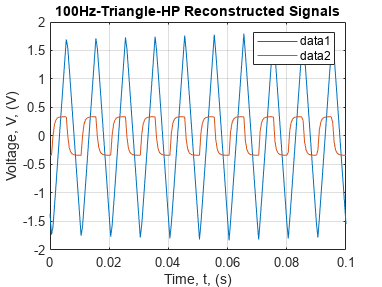


for i = 1:length(filenames)
    %read the data
    [raw, filtered] = readData(filenames(i));
    data = [raw, filtered];
    
    % plot the raw signals
    plot(t(1:50),raw(1:50),"DisplayName","Raw"); 
    hold on;
    plot(t(1:50),filtered(1:50),"DisplayName","Filtered");
    hold off;
    grid on; legend;
    figureTitle = sprintf("%s Recorded Signals",dataNames(i));
    title(figureTitle);
    xlabel("Time, t, (s)"); ylabel("Voltage, V, (V)");
    % save figure
    saveas(gcf,"Graphs/" + figureTitle + ".jpg");
    
    % compute the fft
    dat_hat = fft(data,n,1) / n; % compute the 2 sided fft and scale it
    dat_hat = dat_hat(1:n/2+1,:); % take half of the two sided for conversion to one sided
    dat_hat(2:end-1,:) = 2 * dat_hat(2:end-1,:); % rescale the one sided distribution avoiding the end point which don'e need to be doubled
    
    % plot the ffts
    plot(f,abs(dat_hat));
    grid on; legend(["Raw","Filtered"]);
    figureTitle = sprintf("%s Amplitude Spectrum",dataNames(i));
    title(figureTitle);
    xlabel("Frequency, f, (Hz)"); ylabel("Amplitude, a, (~)");
    % save figure
    saveas(gcf,"Graphs/" + figureTitle + ".jpg");
    
    % reconstruct the original from the ffts
    % dat_hat_2side = [dat_hat(1) dat_hat(2:end)/2 fliplr(conj(dat_hat(2:end)))/2]; % reproduce 2 sided fft
    dat = [ifft(dat_hat(:,1)), ifft(dat_hat(:,2))]; % inverse fft
    
    % plot the reocnstructed signal
    dat = ifft(fft(data,n,1) / n)*n; % reocnstruct and rescale
    plot(t(1:201), dat(1:201,:));
    grid on; legend;
    figureTitle = sprintf("%s Reconstructed Signals",dataNames(i));
    title(figureTitle);
    xlabel("Time, t, (s)"); ylabel("Voltage, V, (V)");
    % save figure
    saveas(gcf,"Graphs/" + figureTitle + ".jpg");
end

function [raw, filtered] = readData(fileName)
    dat = fileread(fileName);
    dat = str2num(dat);
    raw = dat(:,1);
    filtered = dat(:,2);
end
